# Sin Function Test

## Clear Workspace

close all; clearvars; clc;

## Vars

N = 1e3; % sets the length of buffer for preloading
sample_HZ = 1e6; % frequency HZ
timeStep = 1/sample_HZ; % period of the sampling frequency
A = 1; % amplitude p-pk V
f1 = 10e3; % lowest frequency component Hz
f2 = 20e3; % mid frequency component Hz
f3 = 40e3; % highest frequency component Hz
periods = 1/eval(gcd(sym([f1 f2 f3]))); % calculates the length of the period for a periodic
t = (0:timeStep:periods-timeStep)'; % calculates the time vector from the period

## Wave Gen Function

y = A*sin(2*pi*f1*t) + A*sin(2*pi*f2*t) + A*sin(2*pi*f3*t); % calculates the signal along the time vector
numCycles = ceil(N/length(y)); % calculate the number of cycles to make a full buffer for preloading
sine = repmat(y, numCycles, 1); % extends the data vector to match or execed the buffer length

## Plot Waves

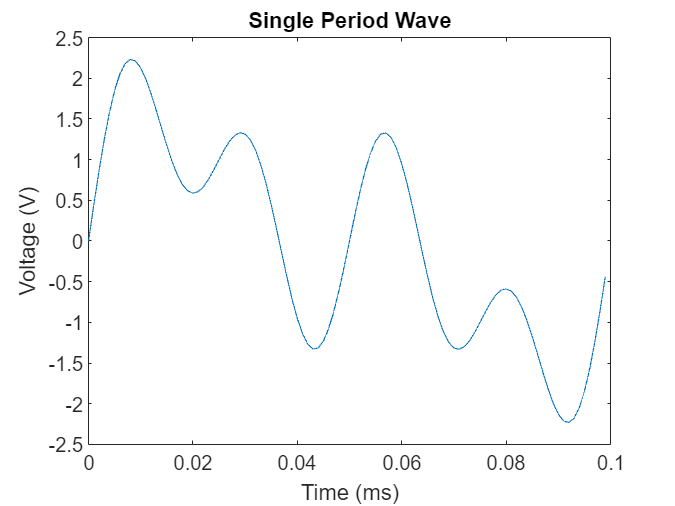

figure
plot(t*1e3, y)
ylabel('Voltage (V)')
xlabel('Time (ms)')
title('Single Period Wave')

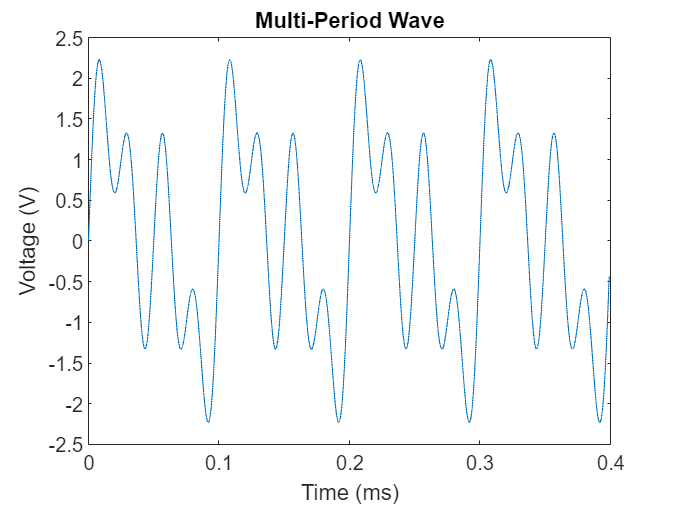


t1 = (0:timeStep:periods*4-timeStep)';
points = floor((periods/timeStep)*4);
figure
plot(t1*1e3, sine(1:points))
ylabel('Voltage (V)')
xlabel('Time (ms)')
title('Multi-Period Wave')

## Plot FFT

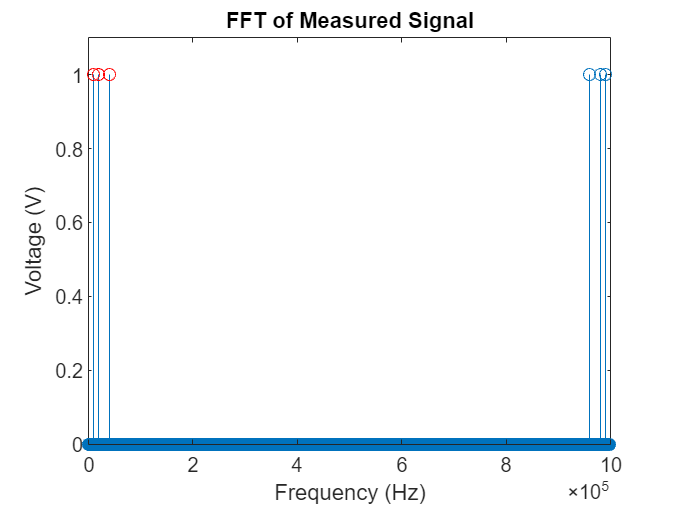

FFT_signal = fft(sine, N);
f_HZ1 = ((0:N-1)*sample_HZ)/N;
figure;
stem(f_HZ1, abs(FFT_signal)/N*2)
title('FFT of Measured Signal')
ylabel('Voltage (V)')
xlabel('Frequency (Hz)')
hold on
plot(f1, 1, 'r o', f2, 1, 'r o', f3, 1, 'r o')
ylim([0 1.1])